% ------------------------------------------------------------
% Store the error sequences (in dB)
% ------------------------------------------------------------

% err_conv = [
%    -38.10, -49.70, -52.20, -53.46, -54.21, -54.73, -55.11, -55.38, -55.58, ...
%    -55.72, -55.81, -55.87, -55.91, -55.92, -55.93, -55.92, -55.91, -55.89, ...
%    -55.86, -55.84, -55.81, -55.78, -55.76, -55.73, -55.71
% ];
%these arrays are taken from signals_100_running/conventional/uniform
%respectively, instead of saving the arrays
err_conv = [ ...
   -50.05, -55.73, -55.90, -55.83, -55.82, -55.83, -55.84, -55.85, ...
   -55.84, -55.83, -55.81, -55.78, -55.76, -55.73, -55.70, -55.67, ...
   -55.65, -55.62, -55.60, -55.57, -55.55, -55.53, -55.52, -55.50, ...
   -55.48, -55.47, -55.46, -55.45, -55.44, -55.43, -55.42, -55.41, ...
   -55.40, -55.40, -55.39, -55.39, -55.38, -55.38, -55.38, -55.37, ...
   -55.37, -55.37, -55.37, -55.36, -55.36, -55.36, -55.36, -55.36, ...
   -55.36, -55.36 ...
];
save('error_conventional_iteration.mat', 'err_conv');

err_run = [ ...
   -24.48, -34.24, -39.17, -42.25, -44.45, -46.19, -47.62, -48.85, ...
   -49.91, -50.85, -51.68, -52.41, -53.08, -53.67, -54.21, -54.70, ...
   -55.15, -55.55, -55.92, -56.26, -56.58, -56.87, -57.13, -57.38, ...
   -57.60, -57.82, -58.01, -58.20, -58.37, -58.53, -58.69, -58.83, ...
   -58.97, -59.09, -59.22, -59.33, -59.44, -59.55, -59.65, -59.74 ...
];
save('error_running_iteration.mat', 'err_run');


err_uniform_100samples = [
   -25.11, -37.77, -44.92, -46.62, -46.37, -45.74, -45.06, -44.42, -43.82, ...
   -43.27, -42.77, -42.30, -41.86, -41.46, -41.08, -40.72, -40.37, -40.05, ...
   -39.74, -39.45, -39.16, -38.89, -38.63, -38.38, -38.13
];

save('error_uniform_100samples_iteration.mat', 'err_uniform_100samples');

err_uniform_90samples = [
   -23.42, -34.37, -39.46, -40.29, -40.06, -39.69, -39.09, -38.49, -37.96, ...
   -37.39, -36.82, -36.27, -35.72, -35.23, -34.74, -34.22, -33.78, -33.24, ...
   -32.90, -32.51, -32.10, -31.73, -31.36, -31.01, -30.67
];
save('error_uniform_90samples_iteration.mat', 'err_uniform_90samples');
% Number of iterations
iters = 1:length(err_run);   % both have 25 points

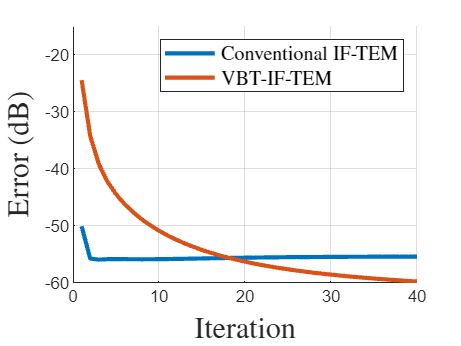


% ------------------------------------------------------------
% Plot
% ------------------------------------------------------------
figure; hold on;

plot(iters, err_conv(1:40), 'LineWidth', 2.5);
plot(iters, err_run,  'LineWidth', 2.5);
%plot(iters, err_uniform_90samples, 'LineWidth', 2.5);
%plot(iters, err_uniform_100samples, 'LineWidth', 2.5);

xlabel('Iteration', 'Interpreter', 'latex', 'FontSize', 18);
ylabel('Error (dB)', 'Interpreter', 'latex', 'FontSize', 18);
%title('Error vs. Iteration: Conventional IF-TEM vs Running IF-TEM');
ylim([-60,-15]);
%legend('Conventional IF-TEM', 'VBT-IF-TEM', 'Uniform (Nyquist)', 'Uniform (1.1*Nyquist)', 'Interpreter', 'latex', 'FontSize', 12, 'Location', 'northeast');
legend('C-IF-TEM', 'Adaptive-NUS', 'Interpreter', 'latex', 'FontSize', 14, 'Location', 'northeast');
grid on;

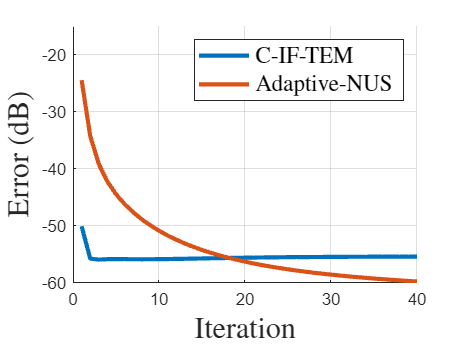

exportgraphics(gcf, 'final_comparison_all_iteration.pdf', ...
    'ContentType', 'vector', ...
    'BackgroundColor', 'none', ...
    'Resolution', 300);